# 绘制旋转多边形

- [Zhihu: https://www.zhihu.com/people/1105936347](https://www.zhihu.com/people/1105936347)

- [Github: https://github.com/AFei19911012](https://github.com/AFei19911012)

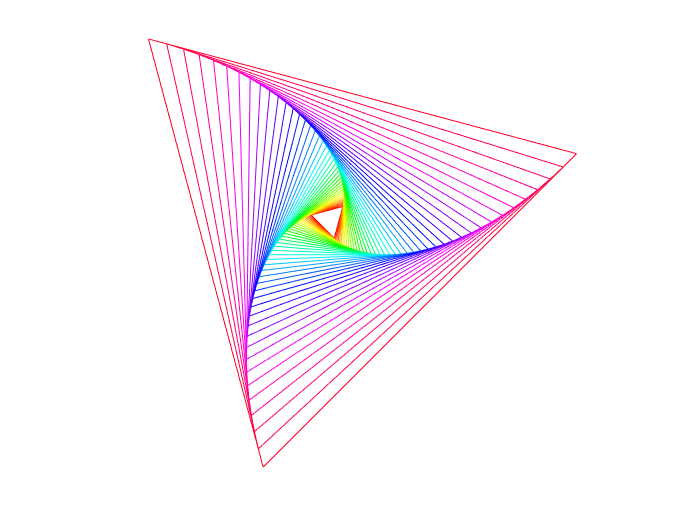

clear;clc;close all;
m = 3;
n = 41;
d_angle = 2.25;
rotate = 45;
shift = [0, 0];
figure
SpiralPolygon(m, n, d_angle, rotate, shift);

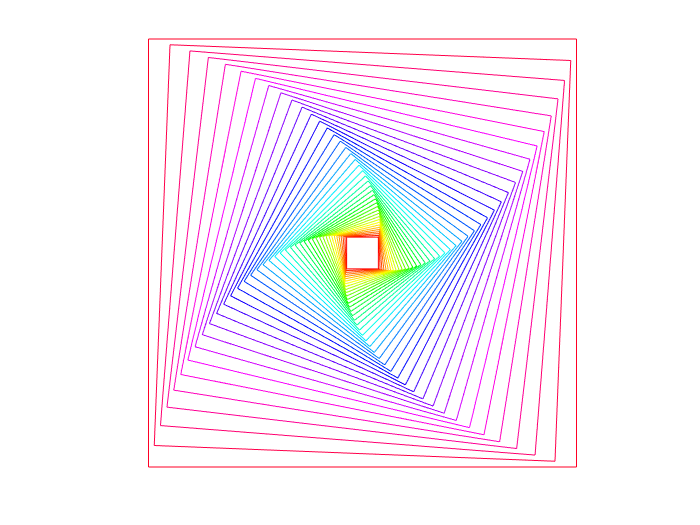

m = 4;
figure
SpiralPolygon(m, n, d_angle, rotate, shift);

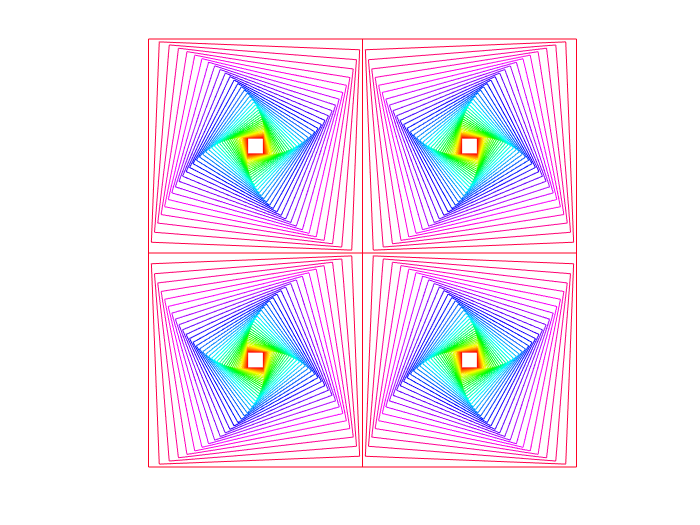

figure;
V = SpiralPolygon(m, n, -d_angle, rotate, shift);
hold on
dx = max(V(1, :)) - min(V(1, :));
dy = max(V(2, :)) - min(V(2, :));
shift = [dx, 0];
SpiralPolygon(m, n, d_angle, rotate, shift);
shift = [dx, dy];
SpiralPolygon(m, n, -d_angle, rotate, shift);
shift = [0, dy];
SpiralPolygon(m, n, d_angle, rotate, shift);
hold off